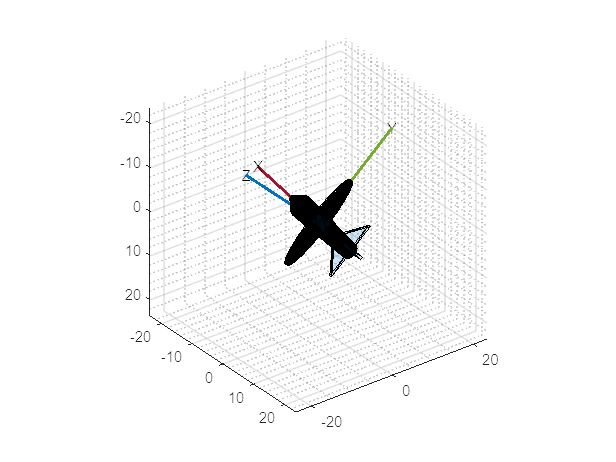

xangle = 90;
yangle = 130;
zangle = 0;
E = [zangle, yangle, xangle];
quat = quaternion(E,'eulerd','ZYX','frame');
poseplot(quat,MeshFileName="fixedwing.stl",ScaleFactor=0.3);

## Body Frame Rotation

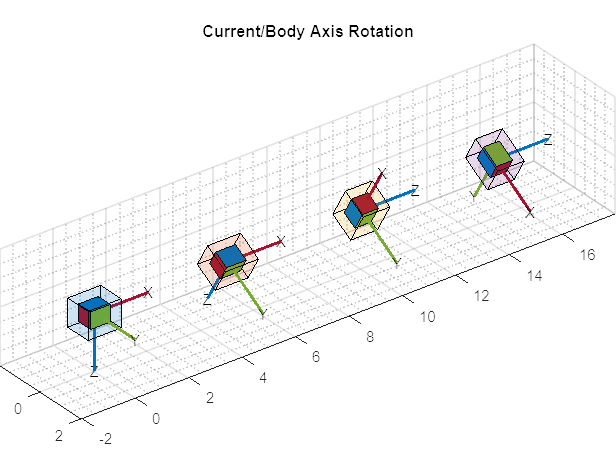

hold off;

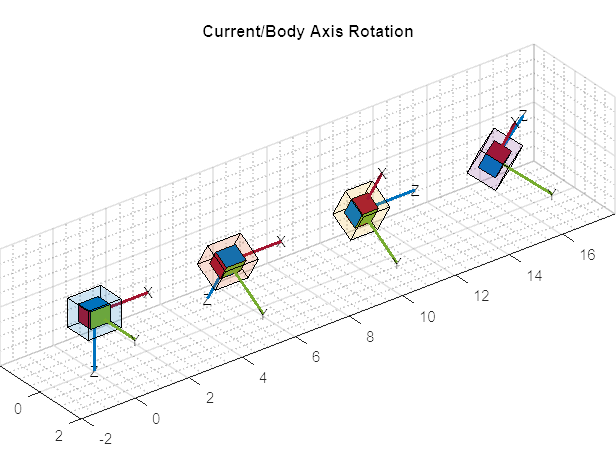

p1 = poseplot;
ylim([-2 2])
xlim([-2 18])
hold on
angles = [0,0,0];
bodySequence = "XYX";
zangle = 90;
yangle = 90;
xangle = 30;
E = [0,0,0];
for i = 1:3
    currentAxis = bodySequence{1}(i);
    switch currentAxis
        case 'Z'
            E(i) = zangle;
        case 'Y'
            E(i) = yangle;
        case 'X'
            E(i) = xangle;
    end
    quat = quaternion(E,'eulerd',bodySequence,'frame');
    poseplot(quat,[5*i,0,0]);
end
legend('Original','1st rotation', '2nd rotation', '3rd rotation');
p1.Parent.Position = [0 0 1 1];
title('Current/Body Axis Rotation')

## Fixed Frame Rotation

hold off;
p1 = poseplot;
ylim([-2 2])
xlim([-2 18])
hold on
fixedSequence = "YZX";
zangle = 90;
yangle = 90;
xangle = 30;
E = [0,0,0];
newSequence = fliplr(fixedSequence{1});
for i = 1:3
    currentAxis = fixedSequence{1}(i);
    switch currentAxis
        case 'Z'
            E(4-i) = zangle;
        case 'Y'
            E(4-i) = yangle;
        case 'X'
            E(4-i) = xangle;
    end
    quat = quaternion(E,'eulerd',newSequence,'frame');
    poseplot(quat,[5*i,0,0]);
end
legend('Original','1st rotation', '2nd rotation', '3rd rotation');
p1.Parent.Position = [0 0 1 1];
title('Fixed Axis Rotation')